INCISO A

% Rango de X
x = -10 : 1 : 10;

% Escalon
unitstep = x>=0;
unitstep2 = x>=-5;

% x[n]
mu = 'unitstep';
mu2 = 'unitstep2';

% y[n]
dir2 = 'dirac(g)';
syms g
g = -5 : 1 : 5;

% Evaluar funciones
val1 = unitstep - unitstep2;
val2 = eval(dir2);

% Normalizar a 1 (dirac)
idx = val2 == Inf;
val2(idx) = 1;

n = (length(val1) + length(val2) - 1);

Grafica de convolucion hecha a mano

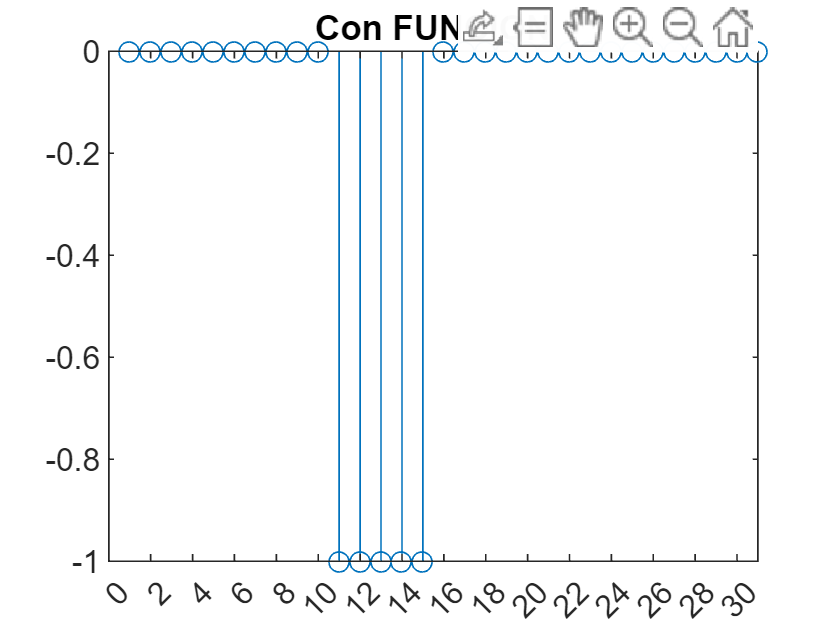

cal = convolucion_disc(val2, val1);

stem(cal);
title('Con FUNCION');
xticks([ 0 : 2 : n ])

Grafica de funcion hecha con FILTER

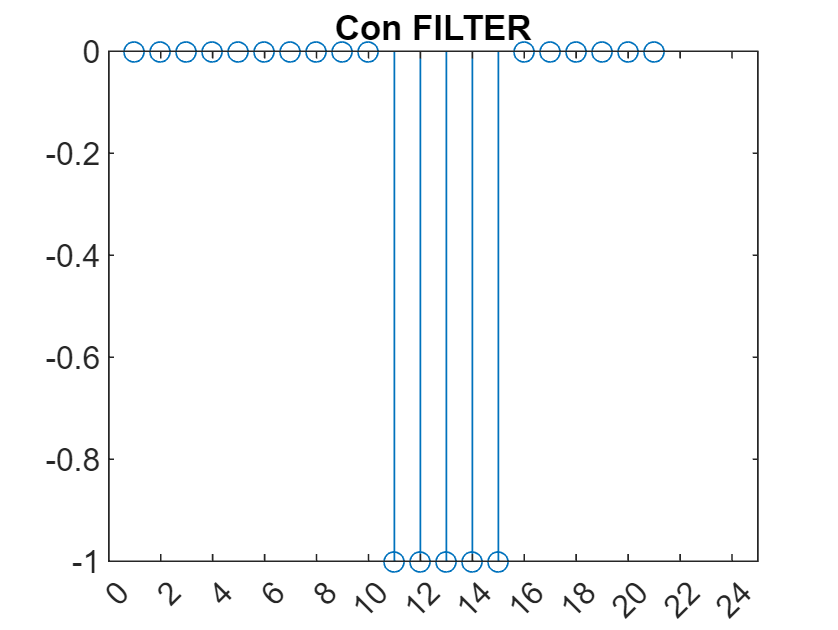

result = filter(val2,1,val1);

stem(result);
title('Con FILTER');
xticks([ 0 : 2 : n ])

INCISO B

% Rango de X
x = -10 : 1 : 10;

% Escalon
unitstep = x>=0;
unitstep2 = x>=-5;

% x[n]
mu = 'unitstep';
mu2 = 'unitstep2';
syms x
x = -5 : 1 : 10;

% y[n]
dir2 = 'dirac(g-5)';
syms g
g = -5 : 1 : 5;

% Evaluar funciones
val1 = eval(mu) - eval(mu2);
val2 = eval(dir2);

% Normalizar a 1 (dirac)
idx = val2 == Inf;
val2(idx) = 1;

n = (length(val1) + length(val2) - 1);

Grafica de convolucion hecha a mano

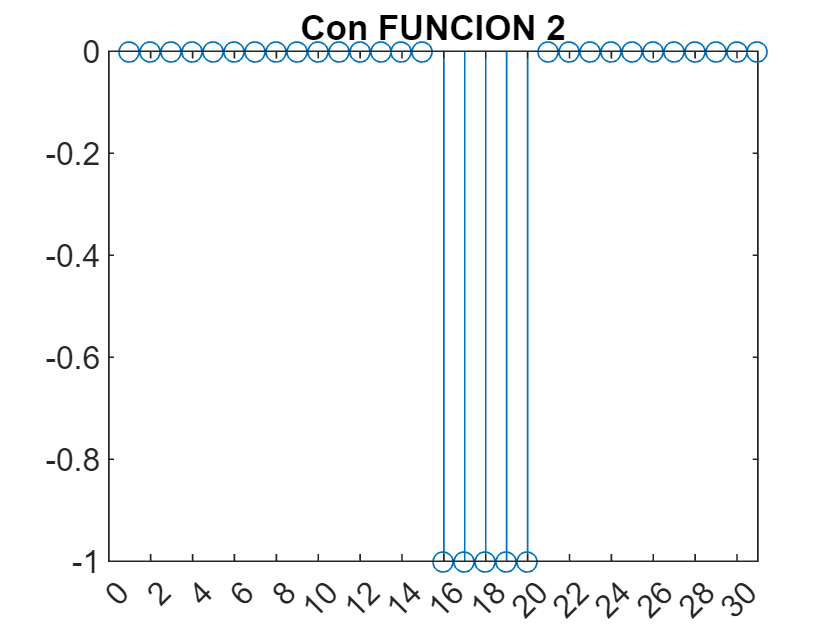

cal = convolucion_disc(val2, val1);

stem(cal);
title('Con FUNCION 2');
xticks([ 0 : 2 : n ])

Grafica de funcion hecha con FILTER

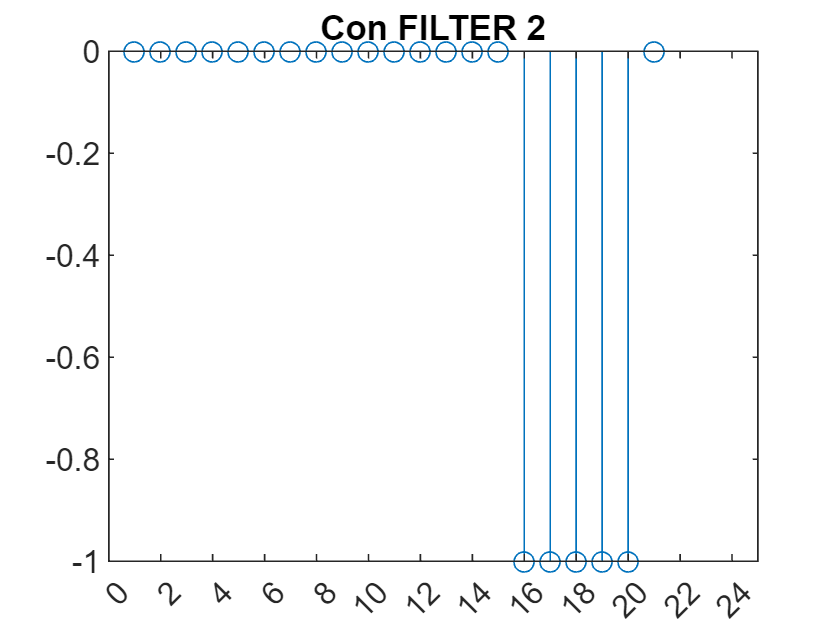

result = filter(val2,1,val1);
 
stem(result);
title('Con FILTER 2');
xticks([ 0 : 2 : n ])

INCISO C

% Rango de X
x = -10 : 1 : 10;

% Escalon
unitstep = x>=0;
unitstep2 = x>=-5;

% x[n]
mu = 'unitstep';
mu2 = 'unitstep2';
syms x

% y[n]
dir2 = 'dirac(g)';
syms g

dir3 = 'dirac(g-10)';
syms g
g = -5 : 1 : 15;

% Evaluar funciones
val1 = eval(mu) - eval(mu2);
val2 = eval(dir2) + eval(dir3);

% Normalizar a 1 (dirac)
idx = val2 == Inf;
val2(idx) = 1;

n = (length(val1) + length(val2) - 1);

Grafica de convolucion hecha a mano

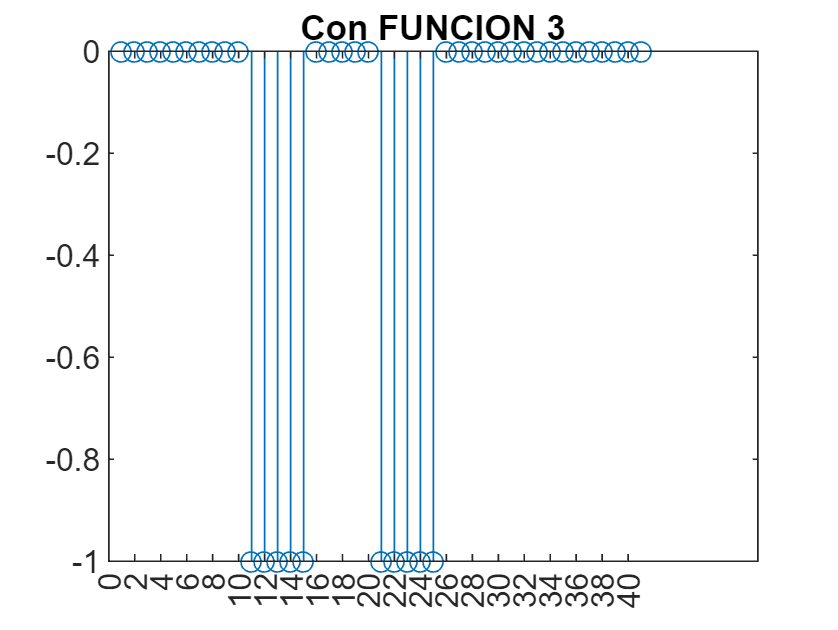

cal = convolucion_disc(val2, val1);

stem(cal);
title('Con FUNCION 3');
xticks([ 0 : 2 : n ])

Grafica de funcion hecha con FILTER

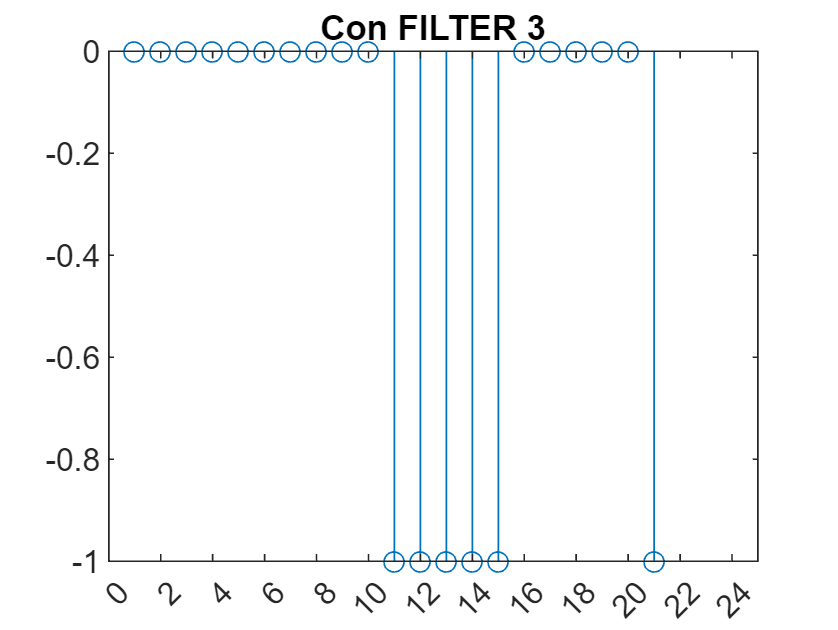

result = filter(val2,1,val1);
 
stem(result);
title('Con FILTER 3');
xticks([ 0 : 2 : n ])

function S = convolucion_disc(h,x)
    nh = length(h);
    nx = length(x);
    % preasignando variables:
    y = zeros(nx,nh);
    Y = zeros(nx,nx+nh-1);
    S = zeros(1,nx+nh-1);
    % creando matriz:
    for j = 1:nx
        for i = 1:nh
            y(j,i) = h(i)*x(j);
        end
        Y(j,j:j-1+nh) = y(j,:);
    end

    % sumando:
    for l = 1:nx + nh - 1
        S(l) = sum(Y(:,l));
    end

end

% Funcion que calcula la convolucion "a mano"